# RSW theory for E&PS Fluids II

#### twnh Feb '18, Feb, May '21

## 1. Linear Waves in the One Layer Rotating Shallow Water System

### 1.1 Velocity Component Form

Define problem

clear
close all
syms k l K f g H
A = [[0,-f,1i*g*k]
    [f,0,1i*g*l]
    [1i*H*k,1i*H*l,0] ]

$$A = \left(\begin{array}{ccc} 0 & -f & g\,k\,\mathrm{i}\\ f & 0 & g\,l\,\mathrm{i}\\ H\,k\,\mathrm{i} & H\,l\,\mathrm{i} & 0 \end{array}\right)$$

Eigenvalue problem to determine frequencies and structures:

[V,Omega] = eig(A) 

$$V = \begin{array}{l} \left(\begin{array}{ccc} -\frac{g\,l\,\mathrm{i}}{f} & \sigma_{4}-\sigma_{1} & -\sigma_{4}-\sigma_{1}\\ \frac{g\,k\,\mathrm{i}}{f} & \sigma_{3}+\sigma_{2} & -\sigma_{3}+\sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{f\,l}{\mathrm{i}\,H\,k^{2}+\mathrm{i}\,H\,l^{2}}\\ \sigma_{2}=\frac{f\,k}{H\,\left(k^{2}\,\mathrm{i}+l^{2}\,\mathrm{i}\right)}\\ \sigma_{3}=\frac{l\,\sigma_{5}}{H\,\left(k^{2}\,\mathrm{i}+l^{2}\,\mathrm{i}\right)}\\ \sigma_{4}=\frac{k\,\sigma_{5}}{\mathrm{i}\,H\,k^{2}+\mathrm{i}\,H\,l^{2}}\\ \sigma_{5}=\sqrt{-f^{2}-H\,g\,k^{2}-H\,g\,l^{2}} \end{array}$$

$$Omega = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \sqrt{-f^{2}-H\,g\,k^{2}-H\,g\,l^{2}} & 0\\ 0 & 0 & -\sqrt{-f^{2}-H\,g\,k^{2}-H\,g\,l^{2}} \end{array}\right)$$

Non-dimensionalize and solve for frequencies and modal structures

omegas = 1i.*subs(diag(Omega),{f,g,H,k,l},{1,1,1,K,0})

$$omegas = \left(\begin{array}{c} 0\\ \sqrt{-K^{2}-1}\,\mathrm{i}\\ -\sqrt{-K^{2}-1}\,\mathrm{i} \end{array}\right)$$

structures = subs(V,{f,g,H,k,l},{1,1,1,K,0})

$$structures = \left(\begin{array}{ccc} 0 & -\frac{\sqrt{-K^{2}-1}\,\mathrm{i}}{K} & \frac{\sqrt{-K^{2}-1}\,\mathrm{i}}{K}\\ K\,\mathrm{i} & -\frac{\mathrm{i}}{K} & -\frac{\mathrm{i}}{K}\\ 1 & 1 & 1 \end{array}\right)$$

#### Plot dispersion relation

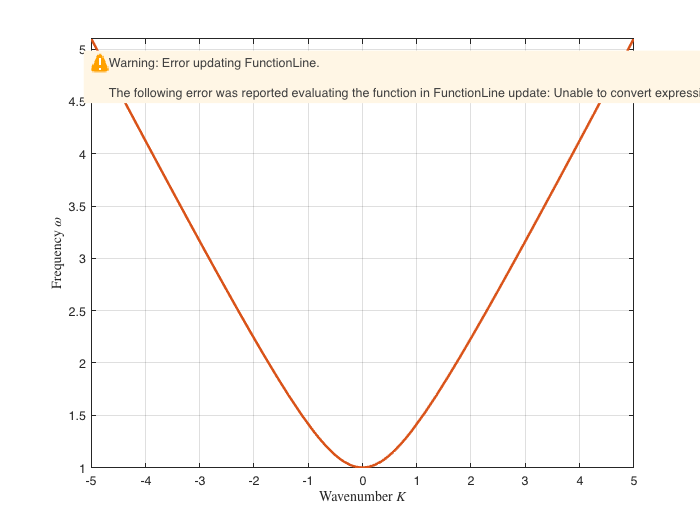

fplot(omegas(1),'LineWidth',2)
hold on
%fplot(omegas(2),'LineWidth',2)       % Negative frequencies
fplot(omegas(3),'LineWidth',2)
grid on
xlabel('Wavenumber $K$','Interpreter','latex') ;
ylabel('Frequency $\omega$','Interpreter','latex') ;

### 1.2 Vorticity and Divergence Form

Define problem

clear
syms k l K f g H
A = [[0,f,0]
    [-f,0,g*(k^2 + l^2)]
    [0,H,0] ]

$$A = \left(\begin{array}{ccc} 0 & f & 0\\ -f & 0 & g\,\left(k^{2}+l^{2}\right)\\ 0 & H & 0 \end{array}\right)$$

Eigenvalue problem to determine frequencies and structures:

[V,Omega] = eig(A) ;

Non-dimensionalize and solve for frequencies and modal structures

omegas = subs(diag(Omega),{f,g,H,k,l},{1,1,1,K,0})

$$omegas = \left(\begin{array}{c} 0\\ \sqrt{K^{2}-1}\\ -\sqrt{K^{2}-1} \end{array}\right)$$

structures = subs(V,{f,g,H,k,l},{1,1,1,K,0})

$$structures = \left(\begin{array}{ccc} K^{2} & 1 & 1\\ 0 & \sqrt{K^{2}-1} & -\sqrt{K^{2}-1}\\ 1 & 1 & 1 \end{array}\right)$$

## One layer beta-plane modes: TO BE COMPLETED!

Define Problem for Vorticity/Divergence form

syms k l K f_0 g H beta
A = [[0,f_0 + 1i*beta*l,0]
    [-f_0 - 1i*beta*l,0,g*(k^2 + l^2)]
    [0,H,0] ]

$$A = \left(\begin{array}{ccc} 0 & f_{0}+\beta \,l\,\mathrm{i} & 0\\ -f_{0}-\beta \,l\,\mathrm{i} & 0 & g\,\left(k^{2}+l^{2}\right)\\ 0 & H & 0 \end{array}\right)$$

[V,Omega] = eig(A) ;

Solve for frequencies and modal structures

omegas = -1i.*diag(Omega)

$$omegas = \left(\begin{array}{c} 0\\ -\sqrt{\beta^{2}\,l^{2}-2\,\beta \,f_{0}\,l\,\mathrm{i}-{f_{0}}^{2}+H\,g\,k^{2}+H\,g\,l^{2}}\,\mathrm{i}\\ \sqrt{\beta^{2}\,l^{2}-2\,\beta \,f_{0}\,l\,\mathrm{i}-{f_{0}}^{2}+H\,g\,k^{2}+H\,g\,l^{2}}\,\mathrm{i} \end{array}\right)$$

structures = V

$$structures = \begin{array}{l} \left(\begin{array}{ccc} \frac{g\,\left(k^{2}+l^{2}\right)}{f_{0}+\beta \,l\,\mathrm{i}} & -\frac{\left(-\beta \,l+f_{0}\,\mathrm{i}\right)\,\mathrm{i}}{H} & -\frac{\left(-\beta \,l+f_{0}\,\mathrm{i}\right)\,\mathrm{i}}{H}\\ 0 & \sigma_{1} & -\sigma_{1}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\beta^{2}\,l^{2}-2\,\beta \,f_{0}\,l\,\mathrm{i}-{f_{0}}^{2}+H\,g\,k^{2}+H\,g\,l^{2}}}{H} \end{array}$$

## 3. Two Layer RSW System

### Non-rotating modes

clear
syms k l K g gp H1 H2 f
A = [[0,g*1i*k,0,g*1i*k]
    [H1*1i*k,0,0,0]
    [0,g*1i*k,0,1i*k*(g+gp)]
    [0,0,1i*k*H2,0] ]

$$A = \left(\begin{array}{cccc} 0 & g\,k\,\mathrm{i} & 0 & g\,k\,\mathrm{i}\\ H_{1}\,k\,\mathrm{i} & 0 & 0 & 0\\ 0 & g\,k\,\mathrm{i} & 0 & k\,\left(g+\mathrm{gp}\right)\,\mathrm{i}\\ 0 & 0 & H_{2}\,k\,\mathrm{i} & 0 \end{array}\right)$$

[V,Omega] = eig(A) ;

Non-dimensionalize and solve for frequencies and modal structures

omegas = 1i.*subs(diag(Omega),{g,gp,H1,H2},{1,1e-1,1,1})

$$omegas = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\\ -\sigma_{2}\\ \sigma_{1}\\ \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{\sqrt{401}\,k^{2}}{20}-\frac{21\,k^{2}}{20}}\,\mathrm{i}\\ \sigma_{2}=\sqrt{\frac{\sqrt{401}\,k^{2}}{20}-\frac{21\,k^{2}}{20}}\,\mathrm{i} \end{array}$$

structures = subs(V,{f,g,H1,H2,k,l},{1,1,1,1,K,0})

$$structures = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}-\sigma_{3} & -\sigma_{2}-\sigma_{4} & \sigma_{1}+\sigma_{3} & \sigma_{2}+\sigma_{4}\\ \sigma_{6} & \sigma_{5} & \sigma_{6} & \sigma_{5}\\ \sigma_{7} & \sigma_{8} & -\sigma_{7} & -\sigma_{8}\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left(-\sigma_{10}-\sigma_{9}-K^{2}\right)}^{3/2}\,\mathrm{i}}{K^{3}}\\ \sigma_{2}=\frac{{\left(\sigma_{9}-\sigma_{10}-K^{2}\right)}^{3/2}\,\mathrm{i}}{K^{3}}\\ \sigma_{3}=\frac{\left(\mathrm{gp}+1\right)\,\sqrt{-\sigma_{10}-\sigma_{9}-K^{2}}\,\mathrm{i}}{K}\\ \sigma_{4}=\frac{\left(\mathrm{gp}+1\right)\,\sqrt{\sigma_{9}-\sigma_{10}-K^{2}}\,\mathrm{i}}{K}\\ \sigma_{5}=\frac{\sigma_{10}-\sigma_{9}+K^{2}}{K^{2}}-\mathrm{gp}-1\\ \sigma_{6}=\frac{\sigma_{10}+\sigma_{9}+K^{2}}{K^{2}}-\mathrm{gp}-1\\ \sigma_{7}=\frac{\sqrt{-\sigma_{10}-\sigma_{9}-K^{2}}\,\mathrm{i}}{K}\\ \sigma_{8}=\frac{\sqrt{\sigma_{9}-\sigma_{10}-K^{2}}\,\mathrm{i}}{K}\\ \sigma_{9}=\frac{K^{2}\,\sqrt{{\mathrm{gp}}^{2}+4}}{2}\\ \sigma_{10}=\frac{K^{2}\,\mathrm{gp}}{2} \end{array}$$

#### Plot dispersion relation

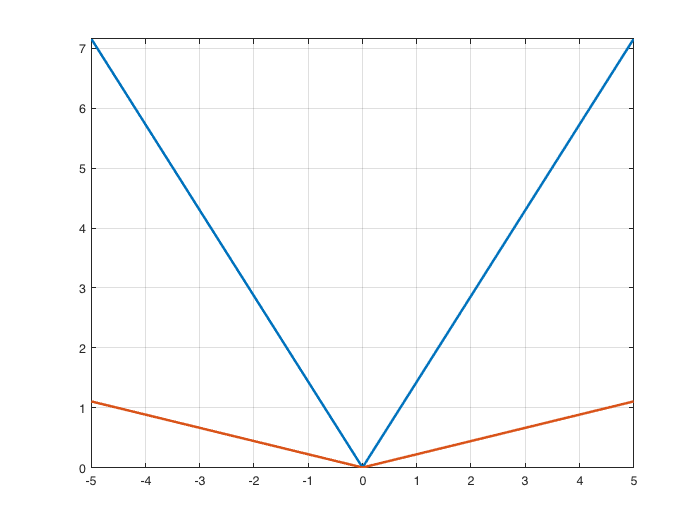

figure
fplot(omegas(1),'LineWidth',2)
hold on
fplot(omegas(2),'LineWidth',2)
grid on

## Two layer f-plane modes

clear all
syms k l omega f g gp H1 H2
A = [[-1i*omega,-f,g*1i*k,0,0,g*1i*k]
    [f,-1i*omega,g*1i*l,0,0,g*1i*l]
    [H1*1i*k,H1*1i*l,-1i*omega,0,0,0]
    [0,0,g*1i*k,-1i*omega,-f,1i*k*(g+gp)]
    [0,0,g*1i*l,f,-1i*omega,1i*l*(g+gp)]
    [0,0,0,H2*1i*k,H2*1i*l,-1i*omega]]

$$A = \left(\begin{array}{cccccc} -\omega \,\mathrm{i} & -f & g\,k\,\mathrm{i} & 0 & 0 & g\,k\,\mathrm{i}\\ f & -\omega \,\mathrm{i} & g\,l\,\mathrm{i} & 0 & 0 & g\,l\,\mathrm{i}\\ H_{1}\,k\,\mathrm{i} & H_{1}\,l\,\mathrm{i} & -\omega \,\mathrm{i} & 0 & 0 & 0\\ 0 & 0 & g\,k\,\mathrm{i} & -\omega \,\mathrm{i} & -f & k\,\left(g+\mathrm{gp}\right)\,\mathrm{i}\\ 0 & 0 & g\,l\,\mathrm{i} & f & -\omega \,\mathrm{i} & l\,\left(g+\mathrm{gp}\right)\,\mathrm{i}\\ 0 & 0 & 0 & H_{2}\,k\,\mathrm{i} & H_{2}\,l\,\mathrm{i} & -\omega \,\mathrm{i} \end{array}\right)$$

detA = det(A)

$$detA = 2\,f^{2}\,\omega^{4}-\omega^{6}-f^{4}\,\omega^{2}+H_{1}\,g\,k^{2}\,\omega^{4}+H_{2}\,g\,k^{2}\,\omega^{4}+H_{2}\,\mathrm{gp}\,k^{2}\,\omega^{4}+H_{1}\,g\,l^{2}\,\omega^{4}+H_{2}\,g\,l^{2}\,\omega^{4}+H_{2}\,\mathrm{gp}\,l^{2}\,\omega^{4}-H_{1}\,f^{2}\,g\,k^{2}\,\omega^{2}-H_{2}\,f^{2}\,g\,k^{2}\,\omega^{2}-H_{2}\,f^{2}\,\mathrm{gp}\,k^{2}\,\omega^{2}-H_{1}\,f^{2}\,g\,l^{2}\,\omega^{2}-H_{2}\,f^{2}\,g\,l^{2}\,\omega^{2}-H_{2}\,f^{2}\,\mathrm{gp}\,l^{2}\,\omega^{2}-H_{1}\,H_{2}\,g\,\mathrm{gp}\,k^{4}\,\omega^{2}-H_{1}\,H_{2}\,g\,\mathrm{gp}\,l^{4}\,\omega^{2}-2\,H_{1}\,H_{2}\,g\,\mathrm{gp}\,k^{2}\,l^{2}\,\omega^{2}$$

detA_nondim = subs(detA,{f,g,l,gp,H1,H2},{1,1,0,1e-1,1,1})

$$detA\_nondim = -\frac{k^{4}\,\omega^{2}}{10}+\frac{21\,k^{2}\,\omega^{4}}{10}-\frac{21\,k^{2}\,\omega^{2}}{10}-\omega^{6}+2\,\omega^{4}-\omega^{2}$$

omegas = solve(detA_nondim == 0)

$$omegas = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ \sigma_{1}\\ \sigma_{2}\\ -\sigma_{1}\\ -\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{21\,k^{2}}{20}-\frac{\sqrt{401}\,k^{2}}{20}+1}\\ \sigma_{2}=\sqrt{\frac{\sqrt{401}\,k^{2}}{20}+\frac{21\,k^{2}}{20}+1} \end{array}$$

#### Plot dispersion relation

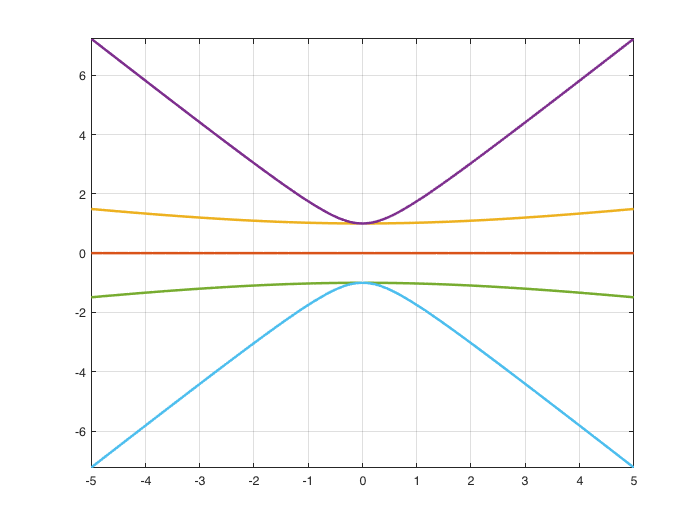

figure
for ff = 1:length(omegas)
    fplot(omegas(ff),'LineWidth',2)
    hold on
end % ff
grid on

## N layer f-plane modes

Define problem

clear
fcoriolis         = 1e-4 ;
gravity           = 9.81 ;
rho0              = 1025 ;
N                 = 4 ;
layer_thicknesses = 200.*ones(N,1) ;
layer_densities   = rho0+10.*(1:N)' ;
reduced_gravities = gravity.*([layer_densities;0]-[0;layer_densities])./rho0 ;
reduced_gravities = reduced_gravities(1:N) ;
defrad            = sqrt(gravity*sum(layer_thicknesses))/fcoriolis ;
kdefrad           = (2*pi)/defrad ;
% NB The first reduced gravity is the actual gravity!
%    This convention is not the same as usual in texts
%    (because I can't define "gp0" as the actual gravity).

Create symbolic variables

syms k l omega f
gp = sym('gp',[1 N+1]) ;
H  = sym('H', [1 N]) ;
A  = sym('A',3*N) ;

Build matrix

for nn = 1:3*N
    A(nn,:)  = 0 ;            % Zero all elements
    A(nn,nn) = -1i*omega ;    % d/dt
end % nn
for nn = 1:3:3*N          % Loop over rows: nn is the x-mom eqn for each layer in turn
    layer = floor((nn-1)/3)+1 ;
    thisH = H(layer) ;
    A(nn,nn+1)   = -f ;            % Coriolis u-mom
    A(nn+1,nn)   =  f ;            % Coriolis v-mom
    A(nn+2,nn)   = 1i*k*thisH ;    % Continuity
    A(nn+2,nn+1) = 1i*l*thisH ;    % Continuity
end % nn

Add pressure gradient terms

for ll = 1:N
    thisrow = ((ll-1)*3)+1 ;
    for mm = 0:ll-1
        for kk = mm+1:N
            thisg   = gp(mm+1) ;
            thiscol = ((kk-1)*3)+3 ;
            A(thisrow  ,thiscol) = A(thisrow  ,thiscol) + 1i*k*thisg ;
            A(thisrow+1,thiscol) = A(thisrow+1,thiscol) + 1i*l*thisg ;
        end % kk
    end % mm
end % ll
detA = det(A) ;

Substitute the parameters

tmp = subs(detA,l,0) ;
tmp = subs( tmp,omega,omega*f) ;
tmp = subs( tmp,k,k*kdefrad) ;
tmp = subs( tmp,f,fcoriolis) ;
for nn = 1:N
    thisgp = reduced_gravities(nn) ;
    thisH  = layer_thicknesses(nn) ;
    tmp    = subs( tmp,gp(nn),thisgp) ;
    tmp    = subs( tmp,H( nn),thisH ) ;
end % nn
detA_subs = vpa(tmp,20) ;

#### Plot dispersion relation

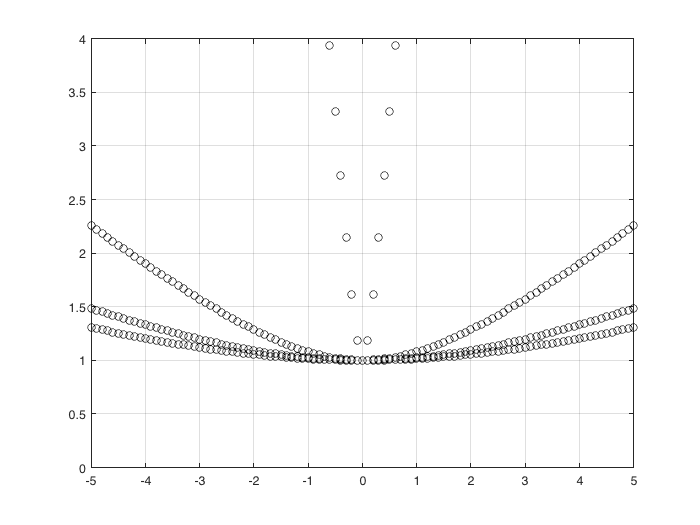

figure
for kk = -5:0.1:5
    % Find the modes
    tmp = subs( detA_subs,k,kk) ;
    omegas = solve(tmp == 0) ;
    
    % Plot
    for ff = 2*N+1:3*N
        plot(kk,real(omegas(ff)),'ko')
        hold on
    end % ff
end %kk
grid on
set(gca,'YLim',[0 4]) ;